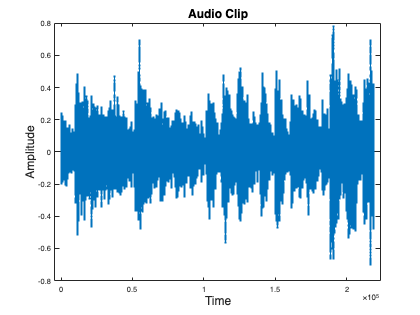

clear
[audio_clip, fs] = audioread('ee110b.m4a');
audio_clip=mean(audio_clip, 2);
sound(audio_clip, fs);
stem(audio_clip, '.')
title("Audio Clip", "FontSize", 16)
xlabel("Time", "FontSize", 16)
ylabel("Amplitude", "FontSize", 16)

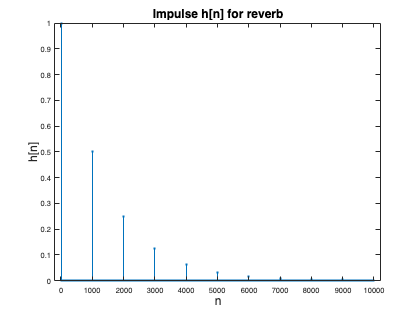

h_reverb = zeros(10000, 1);

for k = 0:9
qk = 1000 * k;      % delay pos
ak = 1 / (2^k);
h_reverb(qk+1) = ak;  % index adjust
end

stem(h_reverb, '.');
title('Impulse h[n] for reverb', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('h[n]', 'FontSize', 16);

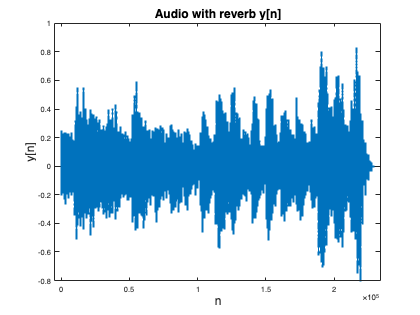

reverb_audio = conv(audio_clip, h_reverb);
sound(reverb_audio, fs);
stem(reverb_audio, '.');
title('Audio with reverb y[n]', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('y[n]', 'FontSize', 16);

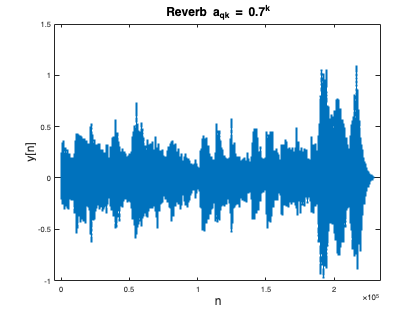

h_reverb = zeros(10000, 1);

for k = 0:9
qk = 1000 * k;
ak = 0.7^k;
h_reverb(qk + 1) = ak;
end

reverb_audio = conv(audio_clip, h_reverb);
sound(reverb_audio, fs);
figure;
stem(reverb_audio, '.');
title('Reverb a_{qk} = 0.7^k', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('y[n]', 'FontSize', 16);

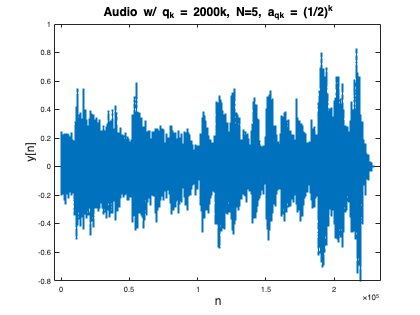

h_reverb = zeros(10000, 1);

for k = 0:4
qk = 2000 * k;
ak = 1 / (2^k);
h_reverb(qk + 1) = ak;
end

reverb_audio = conv(audio_clip, h_reverb);
sound(reverb_audio, fs);  % Optional: listen
figure;
stem(reverb_audio, '.');
title('Audio w/ q_k = 2000k, N=5, a_{qk} = (1/2)^k', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('y[n]', 'FontSize', 16);